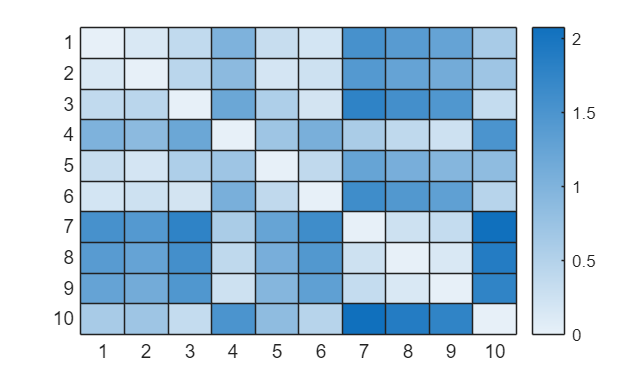

folder_path = "R:\Ophthalmology\Research\SchwartzLab\Xin\project_connectome\4111\exported_color\brain\red_and_raw";
csv_files = dir(fullfile(folder_path, '*.csv'));

num_files = length(csv_files);
br_imids = zeros([num_files, 1]);
%silly linear regression
slopes = zeros([num_files, 3]);
Rsq = zeros([num_files, 2]); 
for i = 1:num_files
    file_path = fullfile(folder_path, csv_files(i).name);
    %filter out the ids of the image
    image_id = regexp(csv_files(i).name, '^\d+', 'match', 'once');
    image_id = str2double(image_id);
    br_imids(i) = image_id;

    data = readtable(file_path);
    data = table2array(data, 1);
    %filtering data before modeling

    %linear regression
    model1 = fitlm(data(:, 1), data(:, 2));
    slopes(i, 1) =table2array(model1.Coefficients(2,1));
    model2 = fitlm(data(:, 2), data(:, 3));
    slopes(i, 2) = table2array(model2.Coefficients(2,1));

    model3 = fitlm(data(:, 1), data(:, 3));
    slopes(i, 3) = table2array(model3.Coefficients(2,1));
    Rsq(i, 1) = model1.Rsquared.Ordinary;
    Rsq(i, 2) = model2.Rsquared.Ordinary;
end
repre2 = [slopes];
dist_matri = zeros([num_files, num_files]);

for i = 1:num_files
    for j = 1:num_files
        distance = norm(repre2(i, :) - repre2(j, :));
        dist_matri(i, j) = distance;
    end
end
figure;
heatmap(dist_matri);

%variant, filtering color pixel > 3* background frame std
folder_path = "R:\Ophthalmology\Research\SchwartzLab\Xin\project_connectome\4111\exported_color\brain\red_and_raw";
csv_files = dir(fullfile(folder_path, '*.csv'));

num_files = length(csv_files);
br_imids = zeros([num_files, 1]);

%silly linear regression
slopes = zeros([num_files, 3]);
intensity = zeros([num_files, 3]);
intercept = zeros([num_files, 3]);
Rsq = zeros([num_files, 2]); 
for i = 1:num_files
    %file_path = fullfile(folder_path, csv_files(i).name);
    % data = readtable(file_path);
    % data = table2array(data, 1);
    %filter out the ids of the image
    image_id = regexp(csv_files(i).name, '^\d+', 'match', 'once');
    image_id = str2double(image_id);
    fprintf('Processing image %d....\n', image_id);
    br_imids(i) = image_id;
    %filtering data before modeling
    bg = get_background(image_id, true);
    bgstd = std(bg, 0, [1, 2]);
    [~, ~, fr, chan] = size(bgstd);
    bgstd = reshape(bgstd, [fr, chan]);
    filtdata = double(GuassianBgFilt(bgstd, fr, chan, image_id, true, 3));
    intensity(i, :) = median(filtdata, 1);
   
    %linear regression
    model1 = fitlm(filtdata(:, 1), filtdata(:, 2));
    slopes(i, 1) = model1.Coefficients.Estimate(2);
    intercept(i, 1) = model1.Coefficients.Estimate(1);
    model2 = fitlm(filtdata(:, 2), filtdata(:, 3));
    slopes(i, 2) = model2.Coefficients.Estimate(2);
    intercept(i, 2) = model2.Coefficients.Estimate(1);

    model3 = fitlm(filtdata(:, 1), filtdata(:, 3));
    slopes(i, 3) = model3.Coefficients.Estimate(2);
    intercept(i, 3) = model3.Coefficients.Estimate(1);
    Rsq(i, 1) = model1.Rsquared.Ordinary;
    Rsq(i, 2) = model2.Rsquared.Ordinary;
end

Processing image 1057....


Getting the background of image 1057...


Filtering the pixel by std of background

Processing image 1058....


Getting the background of image 1058...


Filtering the pixel by std of background

Processing image 1059....


Getting the background of image 1059...


Filtering the pixel by std of background

Processing image 1060....


Getting the background of image 1060...


Filtering the pixel by std of background

Processing image 1061....


Getting the background of image 1061...


Filtering the pixel by std of background

Processing image 1062....


Getting the background of image 1062...


Filtering the pixel by std of background

Processing image 1063....


Getting the background of image 1063...


Filtering the pixel by std of background

Processing image 1064....


Getting the background of image 1064...


Filtering the pixel by std of background

Processing image 1065....


Getting the background of image 1065...


Filtering the pixel by std of background

Processing image 1066....


Getting the background of image 1066...


Filtering the pixel by std of background

% repre2 = [slopes];
% dist_matri = zeros([num_files, num_files]);
% 
% for i = 1:num_files
%     for j = 1:num_files
%         distance = norm(repre2(i, :) - repre2(j, :));
%         dist_matri(i, j) = distance;
%     end
% end
% figure;
% heatmap(dist_matri);

maxchat = max(intensity,[], 1);

minchat = min(intensity, [], 1);
divider = repmat((maxchat-minchat), num_files, 1);
minchat = repmat(minchat, num_files, 1);
norm_med_inten = (intensity-minchat)./divider;

%normalize the intercepts as well
mincept = min(intercept, [], 1);
maxcept = max(intercept, [], 1);
divider_incpt = repmat((maxcept-mincept), num_files, 1);
mincept = repmat(mincept, num_files, 1);
norm_intercept = (intercept-mincept)./divider_incpt;

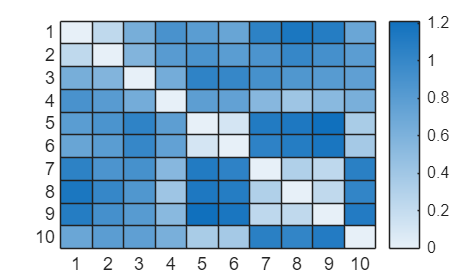

%normalize slope and intercept as their own 
repre2 = [norm_slope(:, 2), norm_slope(:, 3), norm_intercept(:, 1)];
dist_matri = zeros([num_files, num_files]);

for i = 1:num_files
    for j = 1:num_files
        distance = norm(repre2(i, :) - repre2(j, :));
        dist_matri(i, j) = distance;
    end
end
figure;
heatmap(dist_matri);

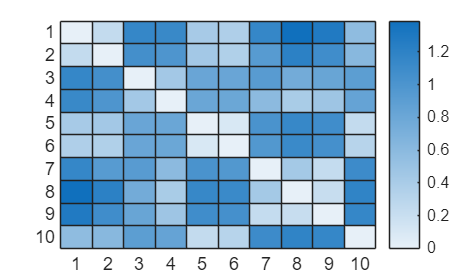

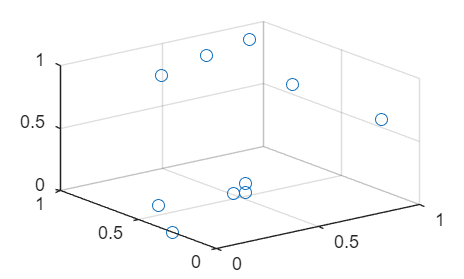

maxp_slope = max(slopes, [], 1);
minp_slope = min(slopes, [], 1);
divider_slope = repmat((maxp_slope-minp_slope), 10, 1);
minp_slope = repmat(minp_slope, 10, 1);
norm_slope = (slopes-minp_slope)./divider_slope;

repre2 = [norm_slope(:, 1), norm_slope(:, 2), norm_slope(:, 3)];
dist_matri = zeros([num_files, num_files]);

for i = 1:num_files
    for j = 1:num_files
        distance = norm(repre2(i, :) - repre2(j, :));
        dist_matri(i, j) = distance;
    end
end
figure;
heatmap(dist_matri);

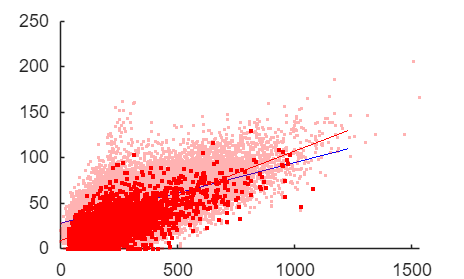

%plot filtering before and after
filtcolor = [];
for i = 1:numel(filted_pix)
    filtcolor=[filtcolor; filted_pix{i}];
end
filtcolor = double(filtcolor);
path = "H:\Data_connectome\trace_pipe_DJ\4111\exported_color\brain\red_and_raw\1057_axon_color_pixeldata.csv";
data = readtable(path);
data = table2array(data);

model_raw1 = fitlm(data(:, 1), data(:, 2));
model_raw2 = fitlm(data(:, 2), data(:, 3));
model_raw3 = fitlm(data(:, 1), data(:, 3));

model_filt1 = fitlm(filtcolor(:, 1), filtcolor(:, 2));
model_filt2 = fitlm(filtcolor(:, 2), filtcolor(:, 3));
model_filt3 = fitlm(filtcolor(:, 1), filtcolor(:, 3));
hold on;
% scatter3(filtcolor(:, 1), filtcolor(:, 2), filtcolor(:, 3), 100, 'blue', '.');
% scatter3(data(:, 1), data(:, 2), data(:, 3),20, 'red', '.');
modraw1x = [0, 0.8*max(data(:, 1), [], 'all')];
modraw1y = [model_raw1.Coefficients.Estimate(1), ...
    model_raw1.Coefficients.Estimate(1)+model_raw1.Coefficients.Estimate(2)*modraw1x(2)];

modfit1x = [0, 0.8*max(filtcolor(:, 1), [], 'all')];
modfit1y = [model_filt1.Coefficients.Estimate(1), ...
    model_filt1.Coefficients.Estimate(1)+model_filt1.Coefficients.Estimate(2)*modfit1x(2)];

h = scatter(filtcolor(:, 1), filtcolor(:, 2), 10, 'blue', '.');
h.MarkerEdgeAlpha = 0.3;
h= scatter(data(:, 1), data(:, 2), 10, 'red', '.');
h.MarkerEdgeAlpha = 0.3;
plot(modraw1x, modraw1y, 'Color', 'red');
plot(modfit1x, modfit1y, 'Color','blue');
hold off;

% folder_path = "R:\Ophthalmology\Research\SchwartzLab\Xin\project_connectome\4111\exported_color\brain\purple";
% csv_files = dir(fullfile(folder_path, '*.csv'));
% 
% num_files = length(csv_files);
% br_imids = zeros([num_files, 1]);
% %silly linear regression
% slopes = zeros([num_files, 3]);
% Rsq = zeros([num_files, 2]); 
% for i = 1:num_files
%     file_path = fullfile(folder_path, csv_files(i).name);
%     %filter out the ids of the image
%     image_id = regexp(csv_files(i).name, '^\d+', 'match', 'once');
%     image_id = str2double(image_id);
%     br_imids(i) = image_id;
% 
%     data = readtable(file_path);
%     data = table2array(data, 1);
%     model1 = fitlm(data(:, 1), data(:, 2));
%     slopes(i, 1) =table2array(model1.Coefficients(2,1));
%     model2 = fitlm(data(:, 2), data(:, 3));
%     slopes(i, 2) = table2array(model2.Coefficients(2,1));
% 
%     model3 = fitlm(data(:, 1), data(:, 3));
%     slopes(i, 3) = table2array(model3.Coefficients(2,1));
%     Rsq(i, 1) = model1.Rsquared.Ordinary;
%     Rsq(i, 2) = model2.Rsquared.Ordinary;
% end
% repre_purple = [slopes(:, 1), slopes(:, 2)];
% dist_matri = zeros([num_files, num_files]);
% repre2 = [repre2;repre_purple];

Error using vertcat
Dimensions of arrays being concatenated are not consistent.

% for i = 1:14
%     for j = 1:14
%         distance = norm(repre2(i, :) - repre2(j, :));
%         dist_matri(i, j) = distance;
%     end
% end
% figure;
% heatmap(dist_matri);

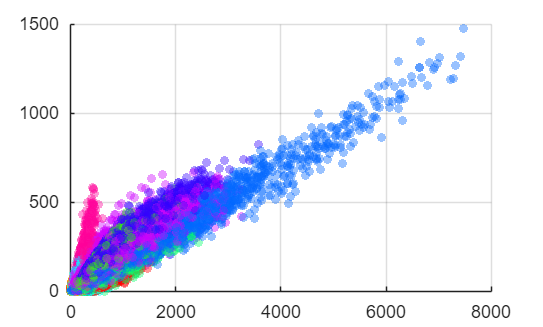

fig = figure(7);          % explicitly grab figure 1
clf(fig);                 % clear that specific figure
ax = axes(fig);           % create axes in it
hold(ax, 'on');
colors = hsv(num_files);  
for i = 1:num_files
    file_path = fullfile(folder_path, csv_files(i).name);
    data = readtable(file_path);
    data = table2array(data);
    sc = scatter3(ax, data(:,1), data(:,2), data(:,3), ...
        20, colors(i,:), 'filled', 'MarkerFaceAlpha', 0.4);
    sc.MarkerEdgeColor = 'none';
end
hold(ax, 'off');
grid(ax, 'on');

%visualization for pixel value linear
i = 8;
fig = figure()

fig =   Figure (11) with properties:

      Number: 11
        Name: ''
       Color: [0.9608 0.9608 0.9608]
    Position: [242 118 560 337.4088]
       Units: 'pixels'

  Show all properties


clf(fig);
file_path = fullfile(folder_path, csv_files(i).name);
fprintf('Loaded: %s\n', file_path);

Loaded: R:\Ophthalmology\Research\SchwartzLab\Xin\project_connectome\4111\exported_color\brain\red_and_raw\1064_red.csv


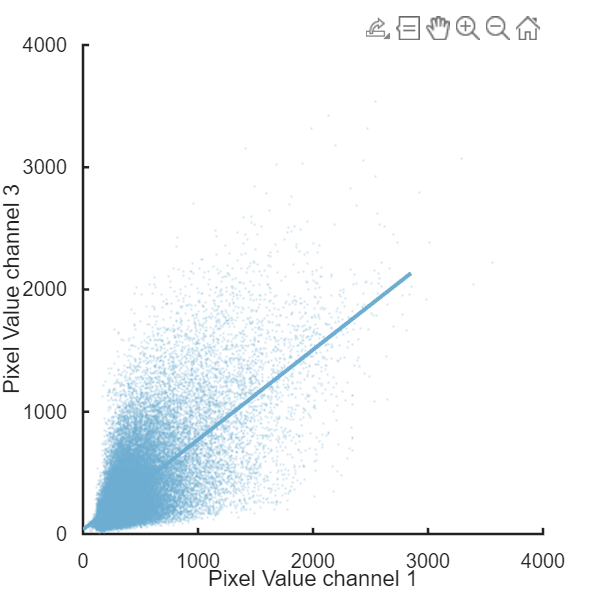

X = readtable(file_path);
X = table2array(X);
colors255 = [[16, 70, 128];
    [49, 124, 183];
    [109, 173, 209];
    [138, 140, 191]];
model1 = fitlm(X(:, 1), X(:, 3));
mod1x = [0, 0.8*max(X(:, 1), [], 'all')];
mod1y = [model1.Coefficients.Estimate(1), ...
    model1.Coefficients.Estimate(1)+model1.Coefficients.Estimate(2)*mod1x(2)];
% 1 and 3
hold on;
ax = gca;
h = scatter(X(:, 1), X(:, 3), 10, repmat(colors255(3,:)/255, height(X), 1), '.');
h.MarkerEdgeAlpha = 0.3;
plot(mod1x, mod1y, 'Color', colors255(3,:)/255, 'LineWidth',2);
ax.LineWidth = 1.2;
yticks([0, 1000, 2000, 3000, 4000]);
xlabel('Pixel Value channel 1');
ylabel('Pixel Value channel 3');
fig.Position = [100, 100, 400, 400];
%axis equal
hold off;

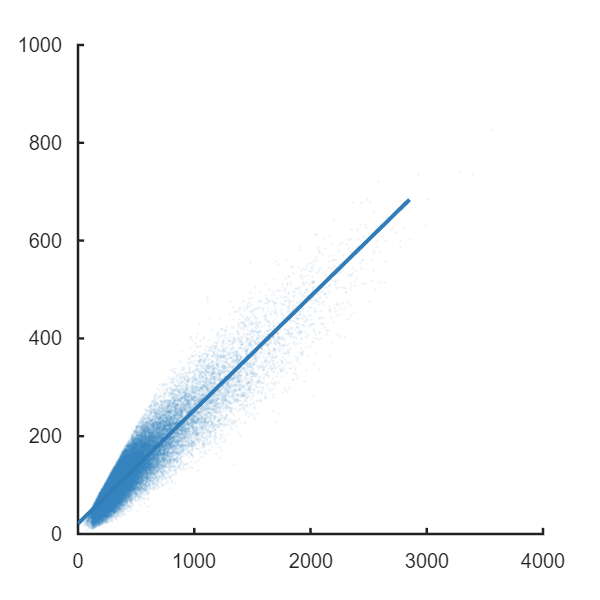

fig = figure();
clf(fig);
model2 = fitlm(X(:, 1), X(:, 2));
mod2x = [0, 0.8* max(X(:, 1), [], 'all')];
mod2y = [model2.Coefficients.Estimate(1), ...
    model2.Coefficients.Estimate(1)+model2.Coefficients.Estimate(2)*mod2x(2)];
% 1 and 3
hold on;
ax = gca;
h = scatter(X(:, 1), X(:, 2), 10, repmat(colors255(2,:)/255, height(X), 1), '.');
h.MarkerEdgeAlpha = 0.1;
plot(mod2x, mod2y, 'Color', colors255(2,:)/255, 'LineWidth',2);
ax.LineWidth = 1.2;
yticks([0, 200, 400, 600, 800, 1000]);
ylim([0, 1000]);
%yticks([0, 1000, 2000, 3000, 4000]);
%xlabel('Pixel Value channel 1');
%ylabel('Pixel Value channel 3');
fig.Position = [100, 100, 400, 400];
%axis equal
hold off;

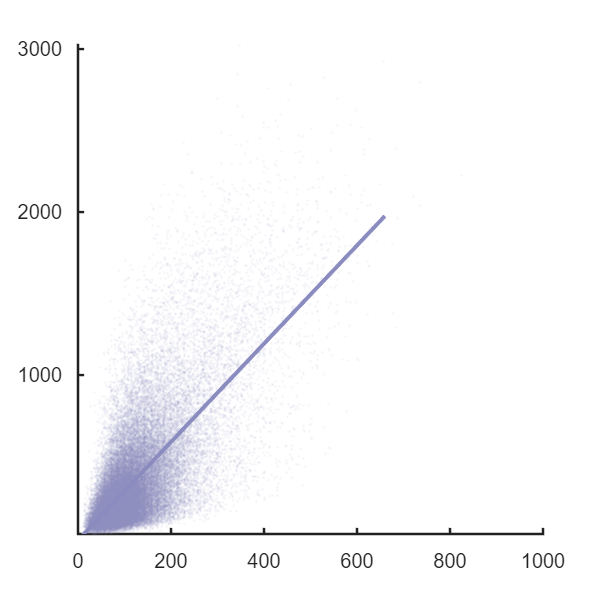

fig = figure();
clf(fig);
model3 = fitlm(X(:, 2), X(:, 3));
mod3x = [0, 0.8* max(X(:, 2), [], 'all')];
mod3y = [model3.Coefficients.Estimate(1), ...
    model3.Coefficients.Estimate(1)+model3.Coefficients.Estimate(2)*mod3x(2)];
% 1 and 3
hold on;
ax = gca;
h = scatter(X(:, 2), X(:, 3), 10, repmat(colors255(4,:)/255, height(X), 1), '.');
h.MarkerEdgeAlpha = 0.1;
plot(mod3x, mod3y, 'Color', colors255(4,:)/255, 'LineWidth',2);
ax.LineWidth = 1.2;
%yticks([0, 200, 400, 600, 800, 1000]);
ylim([0, 3000]);
yticks([0, 1000, 2000, 3000]);
%xlabel('Pixel Value channel 1');
%ylabel('Pixel Value channel 3');
fig.Position = [100, 100, 400, 400];
%axis equal
hold off;

i = 8;
file_path = fullfile(folder_path, csv_files(i).name);
fprintf('Loaded: %s\n', file_path);

Loaded: R:\Ophthalmology\Research\SchwartzLab\Xin\project_connectome\4111\exported_color\brain\red_and_raw\1064_red.csv


X = readtable(file_path);
X = table2array(X);
fig= figure();
clf(fig);
hold on;
colors255 = [[16, 70, 128];
    [49, 124, 183];
    [109, 173, 209];
    [138, 140, 191]];
h = scatter3(X(:, 1), X(:, 2), X(:, 3), 10, repmat(colors255(1,:)/255, height(X), 1), '.');
h.MarkerFaceAlpha = 0.8;
h = scatter3(X(:,1), X(:, 2), zeros([height(X), 1]), 10,  repmat(colors255(2, :)/255, height(X), 1),  '.');
h.MarkerEdgeAlpha = 0.2;
h = scatter3(X(:, 1), zeros([height(X), 1]), X(:, 3),10, repmat(colors255(3, :)/255, height(X), 1),  '.');
h.MarkerEdgeAlpha = 0.2;
h = scatter3(zeros([height(X), 1]), X(:, 2), X(:, 3), 10, repmat(colors255(4, :)/255, height(X), 1), '.');
h.MarkerEdgeAlpha=0.2;
grid on;
ax = gca;
ax.LineWidth = 1.2

ax =   Axes with properties:

             XLim: [0 4000]
             YLim: [0 900]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


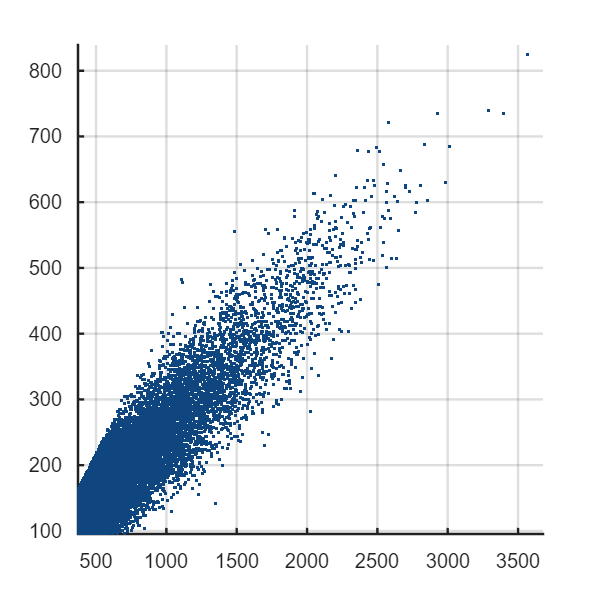

fig.Position = [100, 100, 400, 400];
%xlabel('Pixel value channel 1');
%ylabel('Pixel value channel 2');
%zticks([0, 1000, 2000, 3000, 4000]);
%zlabel('Pixel value channel 3');
hold off;

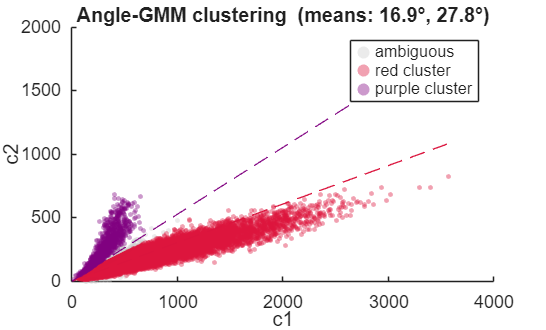

T = X;
c1 = T(:, 1);  c2 = T(:, 2);

% --- Feature: angle from origin ---
theta = atan2(c2, c1);                       % radians

% --- 2-component GMM on theta ---
rng(0);
gm = fitgmdist(theta, 2, 'Replicates', 5);

% Sort components so 1 = shallow (red), 2 = steep (purple)
[mu_sorted, order] = sort(gm.mu);
post = posterior(gm, theta);
post = post(:, order);
p_red    = post(:, 1);
p_purple = post(:, 2);

% --- Hard assignment with ambiguous zone ---
CONF = 0.9;
label = strings(size(c1));
label(:)            = "ambiguous";
label(p_red    > CONF) = "red";
label(p_purple > CONF) = "purple";

% --- Visualize ---
figure; hold on;
sc = @(m, col) scatter(c1(m), c2(m), 6, col, 'filled', 'MarkerFaceAlpha', 0.4);
sc(label=="ambiguous", [0.8 0.8 0.8]);
sc(label=="red",       [0.86 0.08 0.24]);
sc(label=="purple",    [0.5  0.0  0.5]);

% Reference rays at component means
xmax = max(c1);
plot([0 xmax], [0 tan(mu_sorted(1))*xmax], '--', 'Color', [0.86 0.08 0.24]);
plot([0 xmax], [0 tan(mu_sorted(2))*xmax], '--', 'Color', [0.5  0.0  0.5]);

xlabel('c1'); ylabel('c2');
legend({'ambiguous','red cluster','purple cluster'}, 'Location','northeast');
title(sprintf('Angle-GMM clustering  (means: %.1f°, %.1f°)', ...
              rad2deg(mu_sorted(1)), rad2deg(mu_sorted(2))));

f1 = '1064_purple.csv';
f2 = '1064_red.csv';
t = X(label=='purple', :);
t = array2table(t, 'VariableNames', {'c1', 'c2', 'c3'});
writetable(t, f1);

t = X(label=='red', :);
t = array2table(t, 'VariableNames', {'c1', 'c2', 'c3'});
writetable(t, f2);

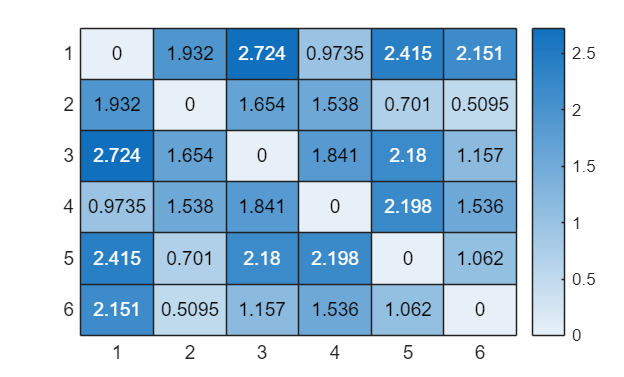

%load rgc axons and color linear regression
folder_path_b =  "R:\Ophthalmology\Research\SchwartzLab\Xin\project_connectome\4111\exported_color\retina";
csv_files_b = dir(fullfile(folder_path_b, '*.csv'));

num_files_b = length(csv_files_b);
ret_imids = zeros([num_files_b, 1]);
slopes_b = zeros([num_files_b, 3]);
Rsq_b = zeros([num_files_b, 2]); 

for i = 1:num_files_b
    file_path = fullfile(folder_path_b, csv_files_b(i).name);
    image_id = regexp(csv_files_b(i).name, '^\d+', 'match', 'once');
    image_id = str2double(image_id);
    ret_imids(i) = image_id;
    
    data = readtable(file_path);
    data = table2array(data, 1);
    model1 = fitlm(data(:, 1), data(:, 2));
    slopes_b(i, 1) =table2array(model1.Coefficients(2,1));
    model2 = fitlm(data(:, 2), data(:, 3));
    slopes_b(i, 2) = table2array(model2.Coefficients(2,1));

    model3 = fitlm(data(:, 1), data(:, 3));
    slopes_b(i, 3) = table2array(model3.Coefficients(2,1));
    Rsq(i, 1) = model1.Rsquared.Ordinary;
    Rsq(i, 2) = model2.Rsquared.Ordinary;
end
repre3 = [slopes_b];
dist_matri = zeros([num_files_b, num_files_b]);
for i = 1:num_files_b
    for j = 1:num_files_b
        distance = norm(repre3(i, :) - repre3(j, :));
        dist_matri(i, j) = distance;
    end
end
figure;
heatmap(dist_matri);

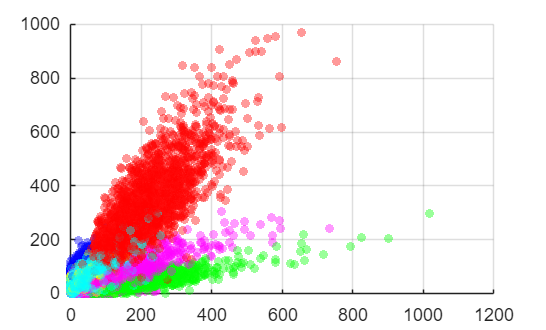

% fig = figure(1);          % explicitly grab figure 1
% clf(fig);                 % clear that specific figure
% ax = axes(fig);           % create axes in it
% hold(ax, 'on');
% colors = hsv(num_files_b);  
% for i = 1:num_files_b
%     file_path = fullfile(folder_path_b, csv_files_b(i).name);
%     data = readtable(file_path);
%     data = table2array(data);
%     sc = scatter3(ax, data(:,1), data(:,2), data(:,3), ...
%         20, colors(i,:), 'filled', 'MarkerFaceAlpha', 0.4);
%     sc.MarkerEdgeColor = 'none';
% end
% hold(ax, 'off');
% grid(ax, 'on');

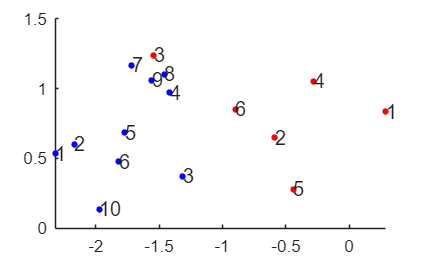

%2d plotting
figure;
hold on;
log_rgc = log(repre3);
log_axon = log(repre2);
scatter(log_rgc(:, 1), log_rgc(:, 2), ...
    10, 'red', 'filled');
for i = 1:height(repre3)
    text(log_rgc(i, 1), log_rgc(i, 2),...
        string(i));
end
scatter(log_axon(:, 1), log_axon(:, 2),...
    10, 'blue', 'filled');

for j = 1:height(log_axon)
    text(log_axon(j, 1),log_axon(j, 2), ...
        string(j));
end

hold off;

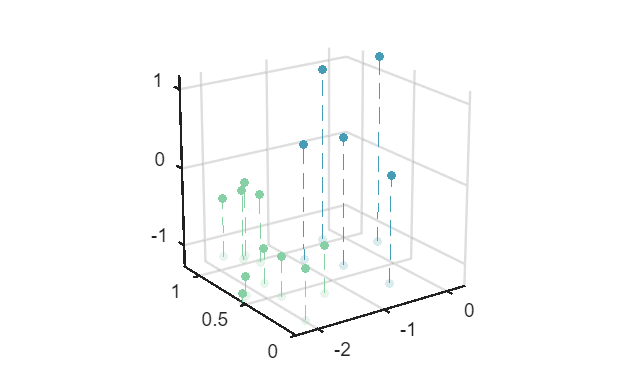

%visualize total in log space, convinient numbering
fig = figure;
clf(fig);
hold on;
log_rgc = log(repre3);
log_axon = log(repre2);
dotcolors = [[70, 156, 180];
 [135, 207, 164];
 [253, 185, 106]];
dotcolors = dotcolors/255;

% --- Determine floor (z = zmin) from data ---
all_z = [log_rgc(:,3); log_axon(:,3)];
zmin = min(all_z);
zrange = max(all_z) - zmin;
zfloor = zmin - 0.05 * zrange;   % drop floor slightly below data

% --- Dashed drop lines (drawn first so dots sit on top) ---
% RGC drop lines
for i = 1:size(log_rgc, 1)
    plot3([log_rgc(i,1) log_rgc(i,1)], ...
          [log_rgc(i,2) log_rgc(i,2)], ...
          [zfloor log_rgc(i,3)], ...
          '--', 'Color', [dotcolors(1,:) 0.25], 'LineWidth', 0.5);
end
% Axon drop lines
for j = 1:size(log_axon, 1)
    plot3([log_axon(j,1) log_axon(j,1)], ...
          [log_axon(j,2) log_axon(j,2)], ...
          [zfloor log_axon(j,3)], ...
          '--', 'Color', [dotcolors(2,:) 0.25], 'LineWidth', 0.5);
end

% --- Floor shadows (projections onto x-y plane) ---
scatter3(log_rgc(:,1), log_rgc(:,2), zfloor*ones(size(log_rgc,1),1), ...
    20, dotcolors(1,:), 'filled', ...
    'MarkerFaceAlpha', 0.2, 'MarkerEdgeColor', 'none');
scatter3(log_axon(:,1), log_axon(:,2), zfloor*ones(size(log_axon,1),1), ...
    20, dotcolors(2,:), 'filled', ...
    'MarkerFaceAlpha', 0.2, 'MarkerEdgeColor', 'none');

% --- Main scatter dots ---
scatter3(log_rgc(:, 1), log_rgc(:, 2), log_rgc(:, 3), ...
    20, dotcolors(1, :), 'filled');
scatter3(log_axon(:, 1), log_axon(:, 2), log_axon(:, 3), ...
    20, dotcolors(2, :), 'filled');

ax = gca;
ax.LineWidth = 1.2;
pbaspect([1 1 1]);
zticks([-1, 0, 1]);
grid on;
view(-35, 20);                          % nice 3D viewing angle
set(ax, 'Projection', 'perspective');   % adds depth foreshortening
hold off;

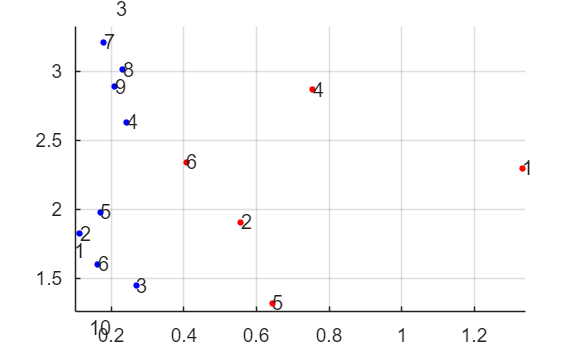

%visualize total in log space, convinient numbering
figure;
hold on;
scatter3(repre3(:, 1), repre3(:, 2), repre3(:, 3), ...
    10, 'red', 'filled');
for i = 1:height(repre3)
    text(repre3(i, 1), repre3(i, 2),repre3(i, 3),...
        string(i));
end
scatter3(repre2(:, 1), repre2(:, 2), repre2(:, 3),...
    10, 'blue', 'filled');

for j = 1:height(log_axon)
    text(repre2(j, 1),repre2(j, 2), repre2(j, 3), ...
        string(j));
end
grid on;
hold off;

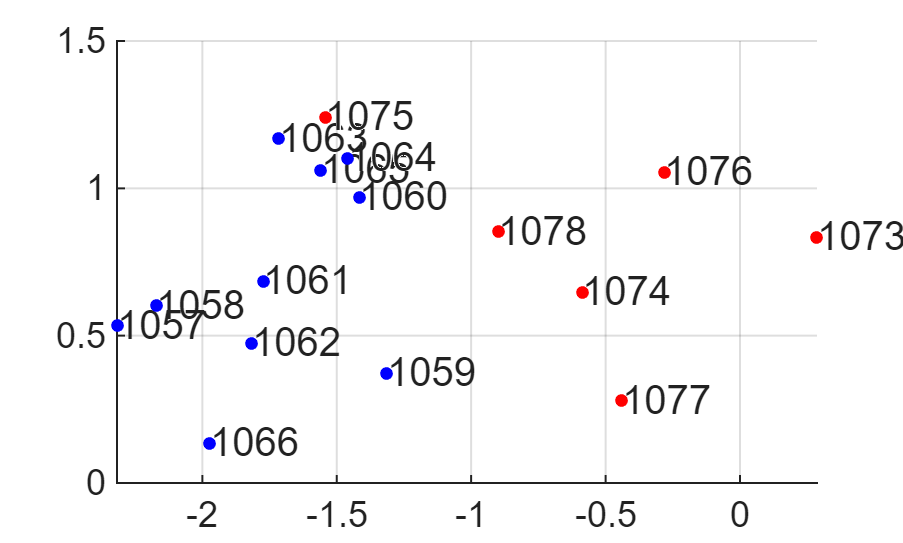

%visualize total in log space, image id
figure;
hold on;
log_rgc = log(repre3);
log_axon = log(repre2);
scatter3(log_rgc(:, 1), log_rgc(:, 2), log_rgc(:, 3), ...
    10, 'red', 'filled');
for i = 1:height(repre3)
    text(log_rgc(i, 1), log_rgc(i, 2),log_rgc(i, 3),...
        string(ret_imids(i)));
end
scatter3(log_axon(:, 1), log_axon(:, 2), log_axon(:, 3),...
    10, 'blue', 'filled');

for j = 1:height(log_axon)
    text(log_axon(j, 1),log_axon(j, 2), log_axon(j, 3), ...
        string(br_imids(j)));
end
grid on;
hold off;

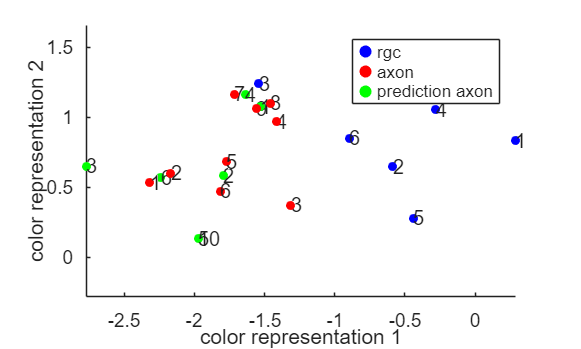

%affine transformation on log space
%sort data first
axon_grouping = {[1,2], [5,6], [4, 7, 8, 9]};
mean_axons = zeros([numel(axon_grouping), 3]);
for i = 1:numel(axon_grouping)
    indx = axon_grouping{i};
    mean_axons(i, :) = mean(repre2(indx, :), 1);
end

sorted_axons = [mean_axons(1, :);
    mean_axons(2, :);
    mean_axons(3, :);
    repre2(10, :);
    ];
logso_axons = transpose(log(sorted_axons));

sorted_rgcs = [repre3(6, :);
    repre3(2, :);
    repre3(1, :);
    repre3(5, :);
    ];
logso_rgcs = transpose(log(sorted_rgcs));

% augment RGC slopes with a row of ones
num_fit = height(sorted_rgcs);
R_aug = [logso_rgcs; ones(1,num_fit)];   % 4x5
% solve: A_aug * R_aug = a_slopes
A_aug = logso_axons / R_aug;        % 3x4, least-squares right-divide

% extract A and b
A = A_aug(:, 1:3);   % 2x2
b = A_aug(:, 4);     % 2x1

% apply to new RGC
prediction_input = A * transpose(log(repre3)) + b;
a_predicted = transpose(prediction_input);

%plot this
figure;
hold on;
scatter3(log_rgc(:, 1), log_rgc(:, 2), log_rgc(:, 3), 20, 'blue', 'filled');
for i = 1:height(repre3)
    text(log_rgc(i, 1), log_rgc(i, 2),log_rgc(i, 3),...
        num2str(i));
end

scatter3(log_axon(:, 1), log_axon(:, 2), log_axon(:, 3), 20, 'red', 'filled');
for j = 1:height(log_axon)
    text(log_axon(j, 1),log_axon(j, 2), log_axon(i, 3), ...
        num2str(j));
end
scatter3(a_predicted(:, 1),a_predicted(:, 2), a_predicted(:, 3), 20, 'green', 'filled');
for i = 1:height(a_predicted)
    text(a_predicted(i, 1), a_predicted(i, 2), a_predicted(i, 3),...
        num2str(i));
end
labels = {'rgc', 'axon', 'prediction axon'};
legend(labels);
%title('Affine transformation');
xlabel('color representation 1');
ylabel('color representation 2');
axis equal;
hold off;


diag_mean = mean(abs(diag(A)));
offdiag_mean = mean(abs(A(~logical(eye(3)))));
fprintf('mean diagonal: %.3f\n', diag_mean);

mean diagonal: 0.798


fprintf('mean off-diagonal: %.3f\n', offdiag_mean);

mean off-diagonal: 1.371


% %affine not log
% 
% %sort data first
% axon_grouping = {[1,2], [5,6], [7, 8, 9]};
% mean_axons = zeros([numel(axon_grouping), 2]);
% for i = 1:numel(axon_grouping)
%     indx = axon_grouping{i};
%     mean_axons(i, :) = mean(repre2(indx, :), 1);
% end

Unable to perform assignment because the size of the left side is 1-by-2 and the size of the right side is 1-by-3.

% 
% sorted_axons = [mean_axons(3, :);
%     mean_axons(1, :);
%     mean_axons(2, :);
%     repre2(10, :);
%     repre2(3, :)];
% 
% 
% sorted_rgcs = [repre3(1, :);
%     repre3(6, :);
%     repre3(2, :);
%     repre3(5, :);
%     repre3(1, :)];
% 
% 
% % augment RGC slopes with a row of ones
% % num_fit = height(sorted_rgcs);
% % R_aug = [logso_rgcs; ones(1,num_fit)];   % 4x5
% % % solve: A_aug * R_aug = a_slopes
% % A_aug = logso_axons / R_aug;        % 3x4, least-squares right-divide
% % 
% % % extract A and b
% % A = A_aug(:, 1:2);   % 2x2
% % b = A_aug(:, 3);     % 2x1
% 
% % augment RGC slopes with a row of ones
% num_fit = height(sorted_rgcs);
% R_aug = [transpose(sorted_rgcs); ones(1,num_fit)];   % 4x5
% % solve: A_aug * R_aug = a_slopes
% A_aug = transpose(sorted_axons) / R_aug;        % 3x4, least-squares right-divide
% 
% % extract A and b
% A = A_aug(:, 1:2);   % 3x3
% b = A_aug(:, 3);     % 3x1
% 
% % apply to new RGC
% prediction_input = A * transpose(repre3) + b;
% a_predicted = transpose(prediction_input);
% 
% %plot this
% figure;
% hold on;
% scatter(repre3(:, 1), repre3(:, 2), 20, 'blue', 'filled');
% for i = 1:height(repre3)
%     text(repre3(i, 1), repre3(i, 2),...
%         num2str(i));
% end
% 
% scatter(repre2(:, 1), repre2(:, 2), 20, 'red', 'filled');
% for j = 1:height(log_axon)
%     text(repre2(j, 1),repre2(j, 2), ...
%         num2str(j));
% end
% scatter(a_predicted(:, 1),a_predicted(:, 2), 20, 'green', 'filled');
% for i = 1:height(sorted_rgcs)
%     text(a_predicted(i, 1), a_predicted(i, 2),...
%         num2str(i));
% end
% labels = {'rgc', 'axon', 'prediction axon'};
% legend(labels);
% title('Affine transformation, regular')
% grid on;
% hold off;

%now do the ratio transformation between axon and rgc
M = [1 0; -1 1; 0 1];
astar1 = repre2(1, :);
astar2 = repre2(2, :);
log_axon = (log(astar1) + log(astar2))/2;
rstar = repre3(3,  :);
log_rgc = log(rstar);
d = transpose(log_axon - log_rgc);

gamma = M\d;
residual = d - M*gamma;
relative_resi = norm(residual)/norm(d);
disp(relative_resi)

d_fit = M*gamma;
log_rgc_all = log(repre3);
logaxon_fitall = zeros([num_files_b, 3]);
for i = 1:height(logaxon_fitall)
    logaxon_fitall(i, :) = log_rgc_all(i, :) + transpose(d_fit);
end

axon_fitall = exp(logaxon_fitall);
disp(axon_fitall);

%now combine the imagened axons and real axons
real_deduced_axons = [repre2; axon_fitall];
total_num = num_files + num_files_b;
moment_of_truth = zeros([total_num, total_num]);
for i = 1:total_num
    for j = 1:total_num
        moment_of_truth(i, j) = norm(real_deduced_axons(i, :)- real_deduced_axons(j, :));
    end
end
figure;
heatmap(moment_of_truth);

% plot the transformation and axon repre in the same figure
figure;
hold on;

scatter3(axon_fitall(:, 1), axon_fitall(:, 2), axon_fitall(:, 3), ...
    10, 'red', 'filled');
for i = 1:height(axon_fitall)
    text(axon_fitall(i, 1), axon_fitall(i, 2), axon_fitall(i, 3),...
        num2str(i));
end
scatter3(repre2(:, 1), repre2(:, 2), repre2(:, 3),...
    10, 'blue', 'filled');

for j = 1:height(repre2)
    text(repre2(j, 1), repre2(j, 2), repre2(j, 3), num2str(j));
end
grid on;
hold off;


L_R = log(sorted_rgcs);   % 3 x K
L_A = log(sorted_axons);   % 3 x K

A = L_A / L_R;         % MATLAB's built-in right-divide does the least-squares fit
                       % equivalent to L_A * pinv(L_R)

% check the residual
L_A_predicted = A * L_R;
residual = L_A - L_A_predicted;
fprintf('residual norm per pair: %.3f\n', norm(residual, 'fro') / sqrt(size(L_R, 2)));

log_allrgcs = log(transpose(repre3));
log_a_predicted_new = exp(A * log_allrgcs);
a_predicted_new = transpose(log_a_predicted_new);
figure;
hold on;

scatter3(a_predicted_new(:, 1), a_predicted_new(:, 2), a_predicted_new(:, 3), ...
    10, 'red', 'filled');
for i = 1:height(a_predicted_new)
    text(a_predicted_new(i, 1), a_predicted_new(i, 2),a_predicted_new(i, 3),...
        num2str(i));
end
scatter3(repre2(:, 1), repre2(:, 2), repre2(:, 3),...
    10, 'blue', 'filled');

for j = 1:height(repre2)
    text(repre2(j, 1), repre2(j, 2), repre2(j, 3), num2str(j));
end
ylim([0,4]);
grid on;
hold off;